## **Initalize**

clear
clc

## Import Data

% Define the Excel file and sheet index
excelFile = "./crops-yield-changes-hadcm3-sres.xls";
% If not working
%excelFile = "C:/Users/.../crops-yield-changes-hadcm3-sres.xls";

% Read the third table from the specified Excel sheet
data = readtable(excelFile, 'Sheet', 3);

clearvars excelFile

% Remove the duplicate name columns
data.Fips_code = []

data = 166×156 table
    BLS_2_Countries__SRES__ABBREVNAME    ISO3v10     WH_2000       RI_2000       MZ_2000      WHA1F2020    RIA1F2020    MZA1F2020    ActChWHA1F2020    ActChRIAIF2020    ActChMZA1F2020    WHA1F2050    RIA1F2050    MZA1F2050    ActChWHA1F2050    ActChRIAIF2050    ActChMZA1F2050    WHA1F2080    RIA1F2080    MZA1F2080    ActChWHA1F2080    ActChRIAIF2080    ActChMZA1F2080    WHA2a2020    RIA2a2020    MZA2a2020    ActChWHA2a2020    ActChRIA2a2020    ActChMZA2a2020    WHA2a2050

data.COUNTRY = []

data = 166×155 table
    BLS_2_Countries__SRES__ABBREVNAME    ISO3v10     WH_2000       RI_2000       MZ_2000      WHA1F2020    RIA1F2020    MZA1F2020    ActChWHA1F2020    ActChRIAIF2020    ActChMZA1F2020    WHA1F2050    RIA1F2050    MZA1F2050    ActChWHA1F2050    ActChRIAIF2050    ActChMZA1F2050    WHA1F2080    RIA1F2080    MZA1F2080    ActChWHA1F2080    ActChRIAIF2080    ActChMZA1F2080    WHA2a2020    RIA2a2020    MZA2a2020    ActChWHA2a2020    ActChRIA2a2020    ActChMZA2a2020    WHA2a2050

## Descriptive statistics

%summary(data)

## PCA

% Original matrix
temp = data;
temp(:, 1) = [];
temp(:, 1) = [];   % remove all columns containing strings
X = table2array(temp);
X(isnan(X)) = 0;
X

X = 1.0e+08 *

    0.0275    0.0034    0.0027   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0         0   -0.0000   -0.0000   -0.0000         0         0
         0         0         0    0.0000    0.0000   -0.0000         0         0         0    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000    0.0000         0         0         0    0.0000    0.0000   -0.0000         0         0         0    0.0000    0.0000    0.0000    


rows = size(X); rows = rows(1)

rows = 166

columns = size(X); columns = columns(2)

columns = 153


% Center reduce the data
Xs = X;

r = sqrt(rows);
for i=1:columns
    m = mean(Xs(:,i));
    s = std(Xs(:,i));
    for j=1:rows
        Xs(j,i) = (Xs(j,i) - m) / (s*r);
    end
end
clearvars i j r m s
Xs

Xs =    -0.0056   -0.0141   -0.0125   -0.0102   -0.0220   -0.0531   -0.0021    0.0100    0.0111   -0.0616   -0.0610   -0.0797   -0.0087   -0.0045    0.0100   -0.0754   -0.0757   -0.0708   -0.0002   -0.0028    0.0081   -0.0182   -0.0177   -0.0438   -0.0051    0.0096    0.0115   -0.0267   -0.0259   -0.0516   -0.0120   -0.0010    0.0111   -0.0707   -0.0709   -0.0714   -0.0163   -0.0089    0.0089   -0.0021   -0.0046   -0.0496   -0.0078    0.0100    0.0115   -0.0301   -0.0276   -0.0520   -0.0124   -0.0042
   -0.0241   -0.0156   -0.0134    0.1804    0.1788    0.0966   -0.0021    0.0100    0.0111    0.0462    0.0529    0.1567   -0.0087   -0.0045    0.0100    0.0518    0.0497    0.1306   -0.0002   -0.0028    0.0081    0.0521    0.0536    0.1008   -0.0051    0.0096    0.0115    0.1192    0.1224    0.1583   -0.0120   -0.0010    0.0111    0.0722    0.0748    0.1405   -0.0163   -0.0089    0.0089    0.1511    0.1468    0.1038   -0.0078    0.0100    0.0115    0.0626    0.0711    0.1536   -0.0124   -


% Compute correlation matrix
R = Xs' * Xs

R =     0.9940    0.7220    0.2866    0.1070    0.0927   -0.0140   -0.0650   -0.5543   -0.1866    0.1197    0.1294    0.0664    0.4514    0.2662   -0.1317    0.1553    0.2072    0.1625   -0.0895    0.4065    0.0073    0.0507    0.0847    0.0004   -0.0085   -0.6225   -0.2610    0.1620    0.1450    0.0609    0.5689    0.0945   -0.2053    0.1688    0.1908    0.1308    0.6945    0.4979   -0.0506    0.1494    0.1038    0.0447    0.4932   -0.4933   -0.2057    0.1173    0.1116    0.0444    0.6268    0.2140
    0.7220    0.9940    0.3407   -0.0849    0.0073   -0.0308   -0.3594   -0.7129   -0.2252    0.1312    0.0919    0.0310    0.4174    0.4314   -0.1682    0.0962    0.1426    0.0949   -0.2653    0.5189   -0.0071    0.0151    0.0199   -0.0212   -0.3484   -0.7819   -0.3143    0.1015    0.0715   -0.0266    0.3991    0.1624   -0.2554    0.1229    0.1201    0.0669    0.4939    0.7089   -0.0725    0.0807    0.0598   -0.0026    0.4081   -0.6202   -0.2510    0.1326    0.0735    0.0100    0.5412    0


% diagonal matrix of eigenvalues (U is the change of basis matrix)
[U, L] = eig(R);
L

L =    -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


% matrix of principal components (coordinates of individuals in the new basis)
F = Xs * U

F =    -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0


% Compute the saturation matrix (coordinates of variables in the new basis)
S = Xs' * F * L^(-1/2)

S =    0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 + 0.0000i   0.00

%writematrix(S,'S.xls')

## Plot

% Find the eigenvalues of the correlation matrix
E = eig(R);

% Find the oqe (number of axes needed)
E = sort(E, 'descend')

E =    56.9662
   25.5890
   18.0061
   14.1083
   12.0915
    8.0342
    4.4673
    4.2997
    1.7990
    0.9184


oqe = (E(1)+E(2)+E(3)+E(4))*100 / columns

oqe = 74.9475


% axis 1 col 153
% axis 2 col 152
% axis 3 col 151
% axis 4 col 150

% Find the coordinates of the individuals in the new basis
disp("Main componants table:")

Main componants table:


disp("Axis 1, Axis 2, Axis 3, Axis 4")

Axis 1, Axis 2, Axis 3, Axis 4


coord = [F(1:end,153:-1:150)]

coord =    -0.2703    0.0079   -0.0889    0.2174
    0.8682    0.2010    0.1447   -0.0203
    0.9307    0.1786    0.1725    0.0320
   -0.0489    0.0339   -0.0516    0.4357
   -0.3465   -0.0394   -0.1222    0.4075
    0.7936   -0.3355   -0.0448    0.3553
    0.7545    0.1695    0.1427   -0.0054
    1.0133   -0.0314   -0.1110   -0.0833
    0.8987    0.1420    0.1420    0.0246
    0.7678    0.1542    0.1285   -0.0124



% Compute the qlt
temp = coord.^2;
temp = sum(temp);

qlt = coord;
for i=1:4
    for j=1:rows
        qlt(j,i) = (qlt(j,i)^2) / temp(i);
    end
end
clearvars i j
qlt

qlt =     0.0013    0.0000    0.0004    0.0034
    0.0132    0.0016    0.0012    0.0000
    0.0152    0.0012    0.0017    0.0001
    0.0000    0.0000    0.0001    0.0135
    0.0021    0.0001    0.0008    0.0118
    0.0111    0.0044    0.0001    0.0089
    0.0100    0.0011    0.0011    0.0000
    0.0180    0.0000    0.0007    0.0005
    0.0142    0.0008    0.0011    0.0000
    0.0103    0.0009    0.0009    0.0000


#### Graphical presentation plan 1-2

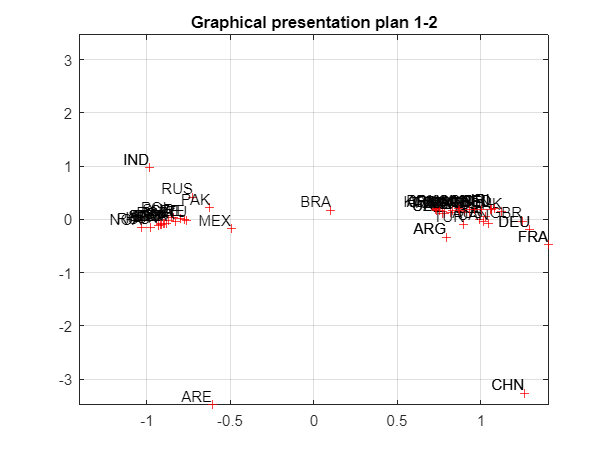

% Find indices where values of qlt(:, 1) are greater than 0.1
% Indices represent the countries well represented by axis 1
indices = qlt(:, 1) > 0.01;  % We consider the first column of 'qlt'
% Filter rows from 'coord' using the indices where 'qlt' > 0.1
filtered_coord = coord(indices, :);
% Plot the values with x component from the 1st column and y component from the 2nd column
plot(filtered_coord(:, 1), filtered_coord(:, 2), 'r+');
hold on

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 1), filtered_coord(i, 2), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Same for indices where values of qlt(:, 2) are greater than 0.001
% Indices represent the countries well represented by axis 2
indices = qlt(:, 2) > 0.001;
filtered_coord = coord(indices, :);
plot(filtered_coord(:, 1), filtered_coord(:, 2), 'r+');% 'bo');

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 1), filtered_coord(i, 2), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

title('Graphical presentation plan 1-2');
grid on
xlim([-max(abs(filtered_coord(:, 1))), max(abs(filtered_coord(:, 1)))]);
ylim([-max(abs(filtered_coord(:, 2))), max(abs(filtered_coord(:, 2)))]);
hold off

#### Graphical presentation plan 1-3

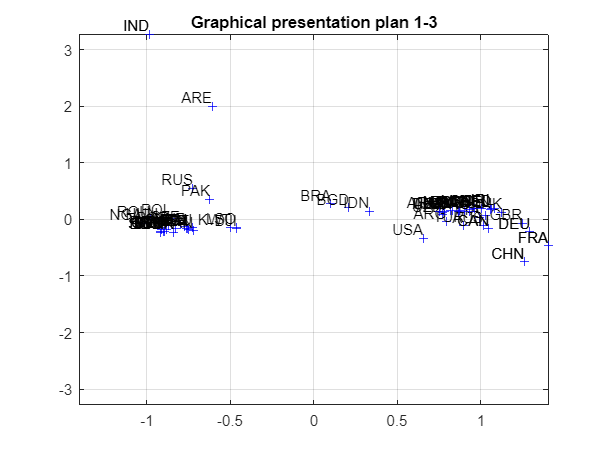

% Find indices where values of qlt(:, 1) are greater than 0.1
% Indices represent the countries well represented by axis 1
indices = qlt(:, 1) > 0.01;  % We consider the first column of 'qlt'
% Filter rows from 'coord' using the indices where 'qlt' > 0.1
filtered_coord = coord(indices, :);
% Plot the values with x component from the 1st column and y component from the 2nd column
plot(filtered_coord(:, 1), filtered_coord(:, 3), 'b+');
hold on

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 1), filtered_coord(i, 3), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end


% Same for indices where values of qlt(:, 2) are greater than 0.001
% Indices represent the countries well represented by axis 3
indices = qlt(:, 3) > 0.001;
filtered_coord = coord(indices, :);
plot(filtered_coord(:, 1), filtered_coord(:, 3), 'b+');% 'bo');

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 1), filtered_coord(i, 3), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end


title('Graphical presentation plan 1-3');
grid on
% Set axis limits to center the plot around (0, 0)
xlim([-max(abs(filtered_coord(:, 1))), max(abs(filtered_coord(:, 1)))]);
ylim([-max(abs(filtered_coord(:, 3))), max(abs(filtered_coord(:, 3)))]);
hold off

#### Graphical presentation plan 2-3

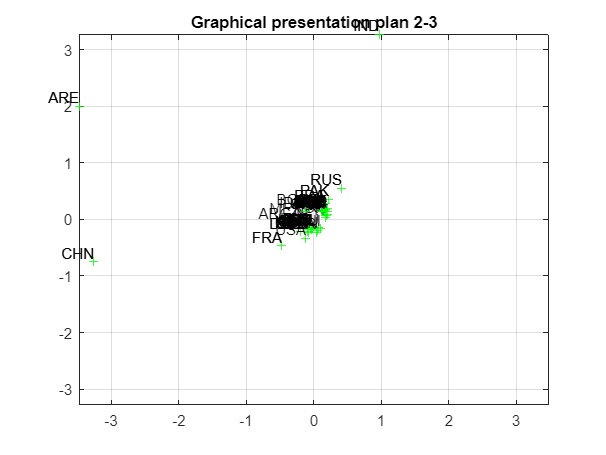

% Find indices where values of qlt(:, 1) are greater than 0.1
% Indices represent the countries well represented by axis 1
indices = qlt(:, 2) > 0.001;  % We consider the first column of 'qlt'
% Filter rows from 'coord' using the indices where 'qlt' > 0.1
filtered_coord = coord(indices, :);
% Plot the values with x component from the 1st column and y component from the 2nd column
plot(filtered_coord(:, 2), filtered_coord(:, 3), 'g+');
hold on

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 2), filtered_coord(i, 3), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end


% Same for indices where values of qlt(:, 2) are greater than 0.001
% Indices represent the countries well represented by axis 3
indices = qlt(:, 3) > 0.001;
filtered_coord = coord(indices, :);
plot(filtered_coord(:, 2), filtered_coord(:, 3), 'g+');% 'bo');

% Plot text labels for each point
country_names = data.ISO3v10(indices);
for i = 1:length(country_names)
    text(filtered_coord(i, 2), filtered_coord(i, 3), country_names{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end


title('Graphical presentation plan 2-3');
grid on
xlim([-max(abs(filtered_coord(:, 2))), max(abs(filtered_coord(:, 2)))]);
ylim([-max(abs(filtered_coord(:, 3))), max(abs(filtered_coord(:, 3)))]);
hold off